clc; clear; close all;

syms l g B_p m_p theta(t) phi theta_0 t
thetaDot = diff(theta, t);
thetaDotDot = diff(thetaDot, t);

%m = l/g
%c = B_p/(g*m_p*l)
%k = 1
m = m_p*l^2

$$m = l^{2}\,m_{p}$$

c = B_p

$$c = B_{p}$$

k = m_p*g*l

$$k = g\,l\,m_{p}$$



%Roots
s1 = -c/(2*m)+sqrt(((c/(2*m)))^2-(k/m))

$$s1 = \sqrt{\frac{{B_{p}}^{2}}{4\,l^{4}\,{m_{p}}^{2}}-\frac{g}{l}}-\frac{B_{p}}{2\,l^{2}\,m_{p}}$$

s2 = -c/(2*m)-sqrt(((c/(2*m)))^2-(k/m))

$$s2 = -\sqrt{\frac{{B_{p}}^{2}}{4\,l^{4}\,{m_{p}}^{2}}-\frac{g}{l}}-\frac{B_{p}}{2\,l^{2}\,m_{p}}$$


wn = sqrt(k/m)

$$wn = \sqrt{\frac{g}{l}}$$

zeta = ((c/(2*m*wn)))

$$zeta = \frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}$$



s11 = (-zeta + 1i*sqrt(1-zeta^2))*wn

$$s11 = \left(-\frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}+\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\,\mathrm{i}\right)\,\sqrt{\frac{g}{l}}$$

s22 = (-zeta - 1i*sqrt(1-zeta^2))*wn

$$s22 = -\left(\frac{B_{p}}{2\,l^{2}\,m_{p}\,\sqrt{\frac{g}{l}}}+\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\,\mathrm{i}\right)\,\sqrt{\frac{g}{l}}$$


test1 = vpa(subs(s1, [l g B_p m_p], [3 9.81 0.1 4.4]), 3)

$$test1 = -0.00126+1.81\,\mathrm{i}$$

test2 = vpa(subs(s11, [l g B_p m_p], [3 9.81 0.1 4.4]), 3)

$$test2 = -0.00126+1.81\,\mathrm{i}$$




ang = theta_0*exp(-zeta*wn*t)*cos(sqrt(1-zeta^2)*wn*t-phi)

$$ang = \theta_{0}\,\cos\left(\varphi -t\,\sqrt{\frac{g}{l}}\,\sqrt{1-\frac{{B_{p}}^{2}}{4\,g\,l^{3}\,{m_{p}}^{2}}}\right)\,{\mathrm{e}}^{-\frac{B_{p}\,t}{2\,l^{2}\,m_{p}}}$$

ang = subs(ang,[l g B_p m_p phi theta_0], [1 9.81 1 5 0 0.2])

$$ang = \frac{{\mathrm{e}}^{-\frac{t}{10}}\,\cos\left(\frac{\sqrt{980}\,t}{10}\right)}{5}$$

fplot(ang, [0 10])
hold on
f = subs(0.2*exp(-zeta*wn*t),[l g B_p m_p phi theta_0], [1 9.81 1 5 0 0.2])

$$f = \frac{{\mathrm{e}}^{-\frac{t}{10}}}{5}$$

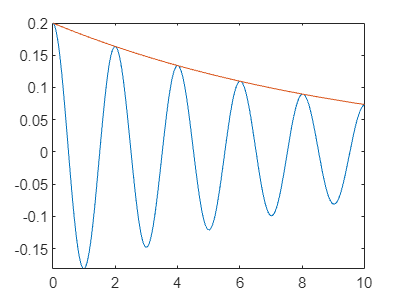

fplot(f, [0 10])